# Antenna-to-Bits Beamformer Example

## Introduction

We start with a basic design: BFIC+PA+Antenna array achieving an EIRP of ~33dBm. Goal is to increase the EIRP above 42dBm, with minimal EVM (below 3%) and keeping the same BFIC and PA hardware components. An AI agent will help you in achieving your goal.

The first four elements: IF filter+LNA+Tuner+Splitter are representative of the BFIC. This is followed by a PA and the antenna array, initially built with 4 dipoles.

clear; clc; close all
addpath('helpers');

## Global parameters

fIF = 4e9;
fLO = 8e9;
fRF = fIF+fLO;
lambda = physconst("LightSpeed")/fRF;
BW = 100e6;
N = 4;
loadOutWaveforms = 1;

## Stage 1 - IF filter

IF filter to remove possible spurs coming from the DAC.

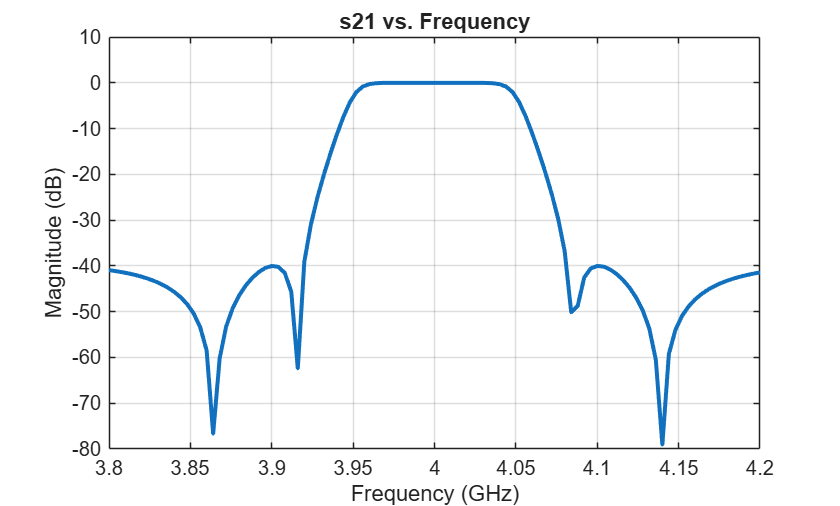

ifFilter = rffilter("Name","IFfilter", FilterType="InverseChebyshev",...
    ResponseType="Bandpass", FilterOrder=5, ...
    PassbandFrequency=[-BW/2 BW/2]+fIF, PassbandAttenuation=3);
rfplot(ifFilter, linspace(-BW*2+fIF, BW*2+fIF, 101));

The ~10ns variation in the group delay should not be of concern as they are negligible compared to the cyclic prefix (~4.7 µs at 30 kHz SCS) and will not cause ISI. The equalizer will handle it without issue.

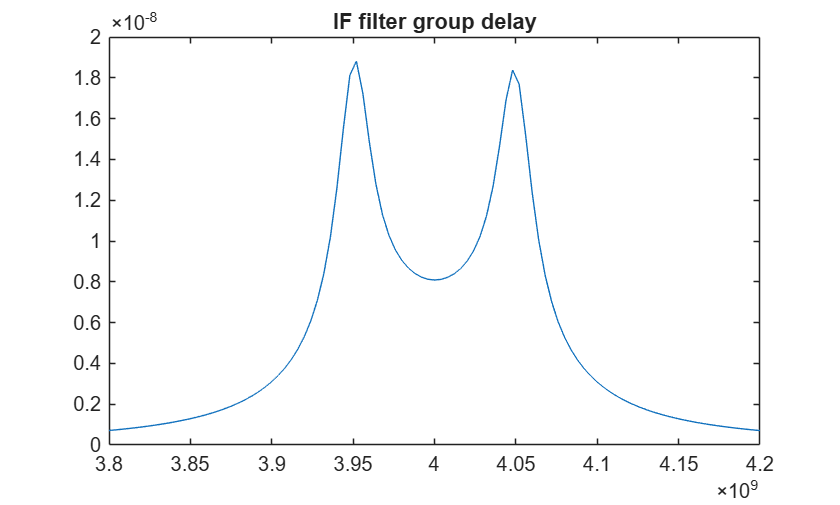

ifFilterGP = groupdelay(ifFilter, linspace(-BW*2+fIF, BW*2+fIF, 101));
figure; plot(linspace(-BW*2+fIF, BW*2+fIF, 101),ifFilterGP); 
title("IF filter group delay");

elements(1) = ifFilter;

## Stage 2 - LNA

The LNA model includes noise, nonlinearity, and S-parameters. This is a wideband component with excellent performance.

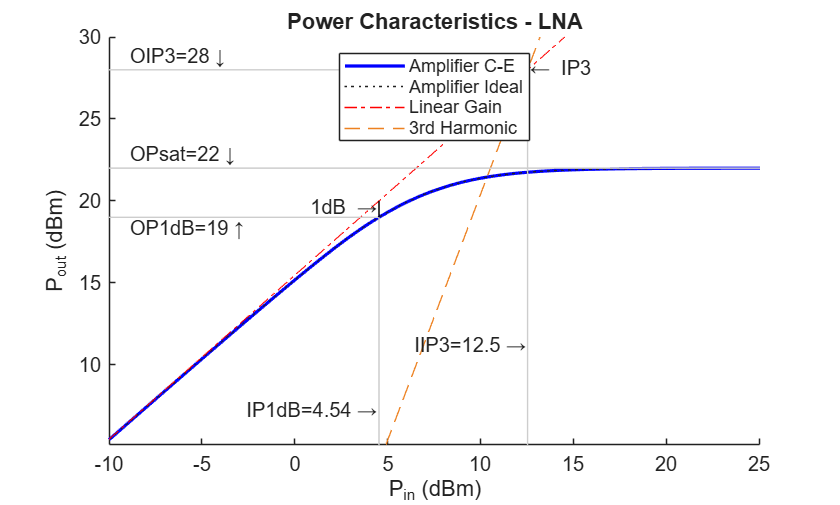

lnaSparamFileName = "CMD240withNF.s2p";
lna = amplifier("Name","LNA",...
    Model="sparam",FileName=lnaSparamFileName, ...
    OIP3=28, OP1dB=19, OPsat=22);
rfplot(lna)

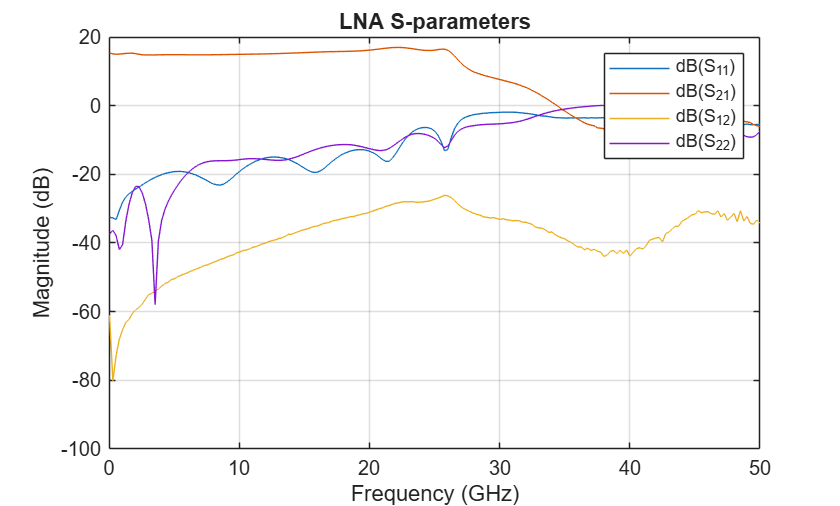

figure; rfplot(sparameters(lnaSparamFileName)); title("LNA S-parameters")

elements(2) = lna;

## Stage 3 - RF Tuner (RF upconverter)

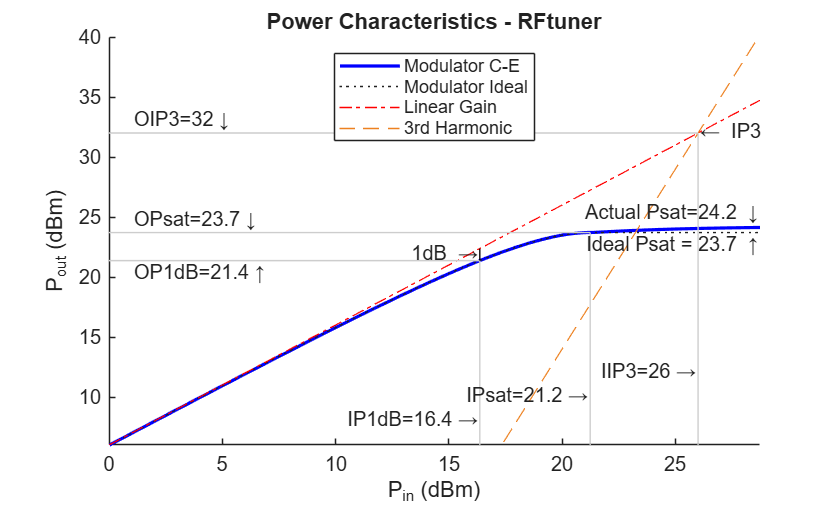

rfTuner = modulator("Name","RFtuner", Model="mod", LO=fLO, ...
    Gain=6, NF=3, OIP3=32);
rfplot(rfTuner)

elements(3) = rfTuner;

## Stage 4 - Wilkinson corporate splitter

The substrate type and thickness was suggested by the AI agent to keep trace thickness sufficiently large and reduce insertion loss.

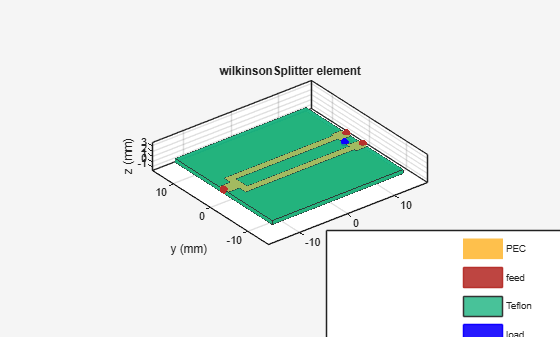

d = dielectric('Teflon');
w = wilkinsonSplitter('Substrate',d);
w.Height = 0.75e-3;
w.GroundPlaneWidth =0.05;
e = design(w, fRF);
show(e)

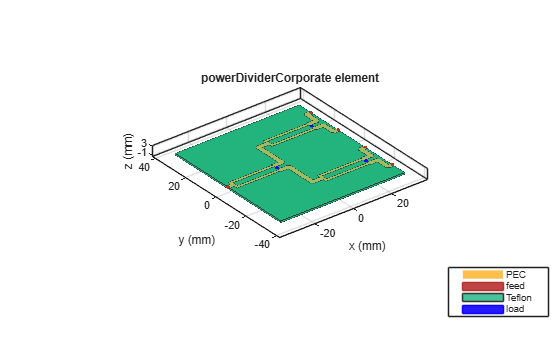

splitterCorporate = design(powerDividerCorporate(NumOutputPorts=N,SplitterElement=e), fRF);
splitterCorporate.PortSpacing = 0.018;
splitterCorporate.GroundPlaneWidth = 0.07;
figure; show(splitterCorporate)

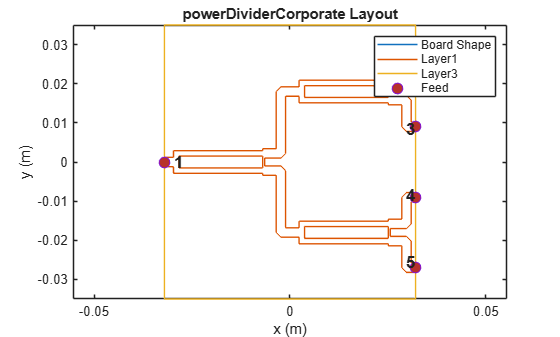

figure; layout(splitterCorporate)

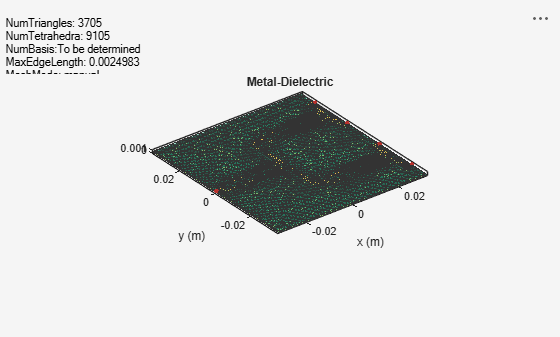

figure; mesh(splitterCorporate,'MaxEdgeLength',lambda/10);

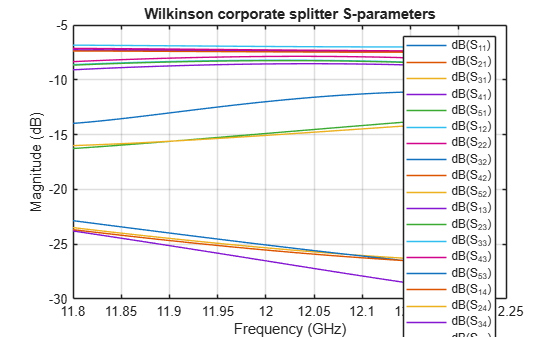

load WilkinsonSplitterData.mat;
splitterSparam = sparameters(splitterCorporate,[-2*BW 2*BW]+fRF,...
    'SweepOption','interp');
%save('WilkinsonSplitterData.mat','splitterCorporate','splitterSparam');
figure; rfplot(splitterSparam); title("Wilkinson corporate splitter S-parameters")

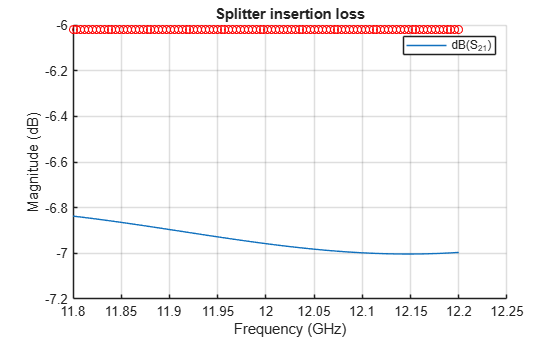

figure; hold on; rfplot(splitterSparam,2,1); title("Splitter insertion loss"); 
plot(splitterSparam.Frequencies/1e9,-10*log10(N),'ro-');

splitter = nport("Name","WilkinsonSplitter",...
    NetworkData=sparameters(splitterSparam));
elements(4) = splitter;

## Stage 5 - Power Amplifier

Notice the soft compression typical of GaN devices.

pa = amplifier("Name","PA",Model="poly", ...
    Gain=25, NF=6, OIP3=45, OP1dB=33, OPsat=37.5);
rfplot(pa);
elements(5) = pa;

## Stage 6 Antenna - dipole to start with ...

rfAntenna = design(dipole, fRF);
figure; pattern(rfAntenna, fRF);
patternAntenna=pattern(rfAntenna, fRF);
antennaSparam = sparameters(rfAntenna, [-2*BW, 2*BW]+fRF, ...
    'SweepOption', 'interp');
S = sparameters(rfAntenna,fRF);
figure; rfplot(antennaSparam);
budgetAntenna = rfantenna("Gain",pattern(rfAntenna, fRF,0,0),"Z",...
    s2z(S.Parameters));
elements(6) = budgetAntenna;

## RF Budget analysis in quasi-linear region (1 channel)

Pin = -20;   % design input power [dBm]
b = rfbudget(Elements=elements, InputFrequency=fIF, ...
    AvailableInputPower=Pin, SignalBandwidth=BW)

b =   rfbudget with properties:

               Elements: [1x6 rf.internal.rfbudget.Element]
         InputFrequency:   4 GHz
    AvailableInputPower: -20 dBm
        SignalBandwidth: 100 MHz
                 Solver: Friis      
             AutoUpdate: true

   Analysis Results
        OutputFrequency: (GHz) [        4       4      12     12     12     12]
            OutputPower: (dBm) [      -20  -5.172  0.8275  -6.13  18.87  20.84]
         TransducerGain: (dB)  [7.946e-13   14.83   20.83  13.87  38.87  40.84]
                     NF: (dB)  [        0     2.9   2.972  3.029  3.286  3.286]
                   IIP3: (dBm) [      Inf   13.13   9.006  9.006  4.296  4.296]
                   OIP3: (dBm) [      Inf      28   29.88  22.92  43.21  43.07]
                    SNR: (dB)  [    73.98   71.08      71  70.95  70.69  70.69]
                   EIRP: (dBm) [    20.84]                                     
            Directivity: (dBi) [      2.

show(b)

You can verify with HB that we are far away from compression.

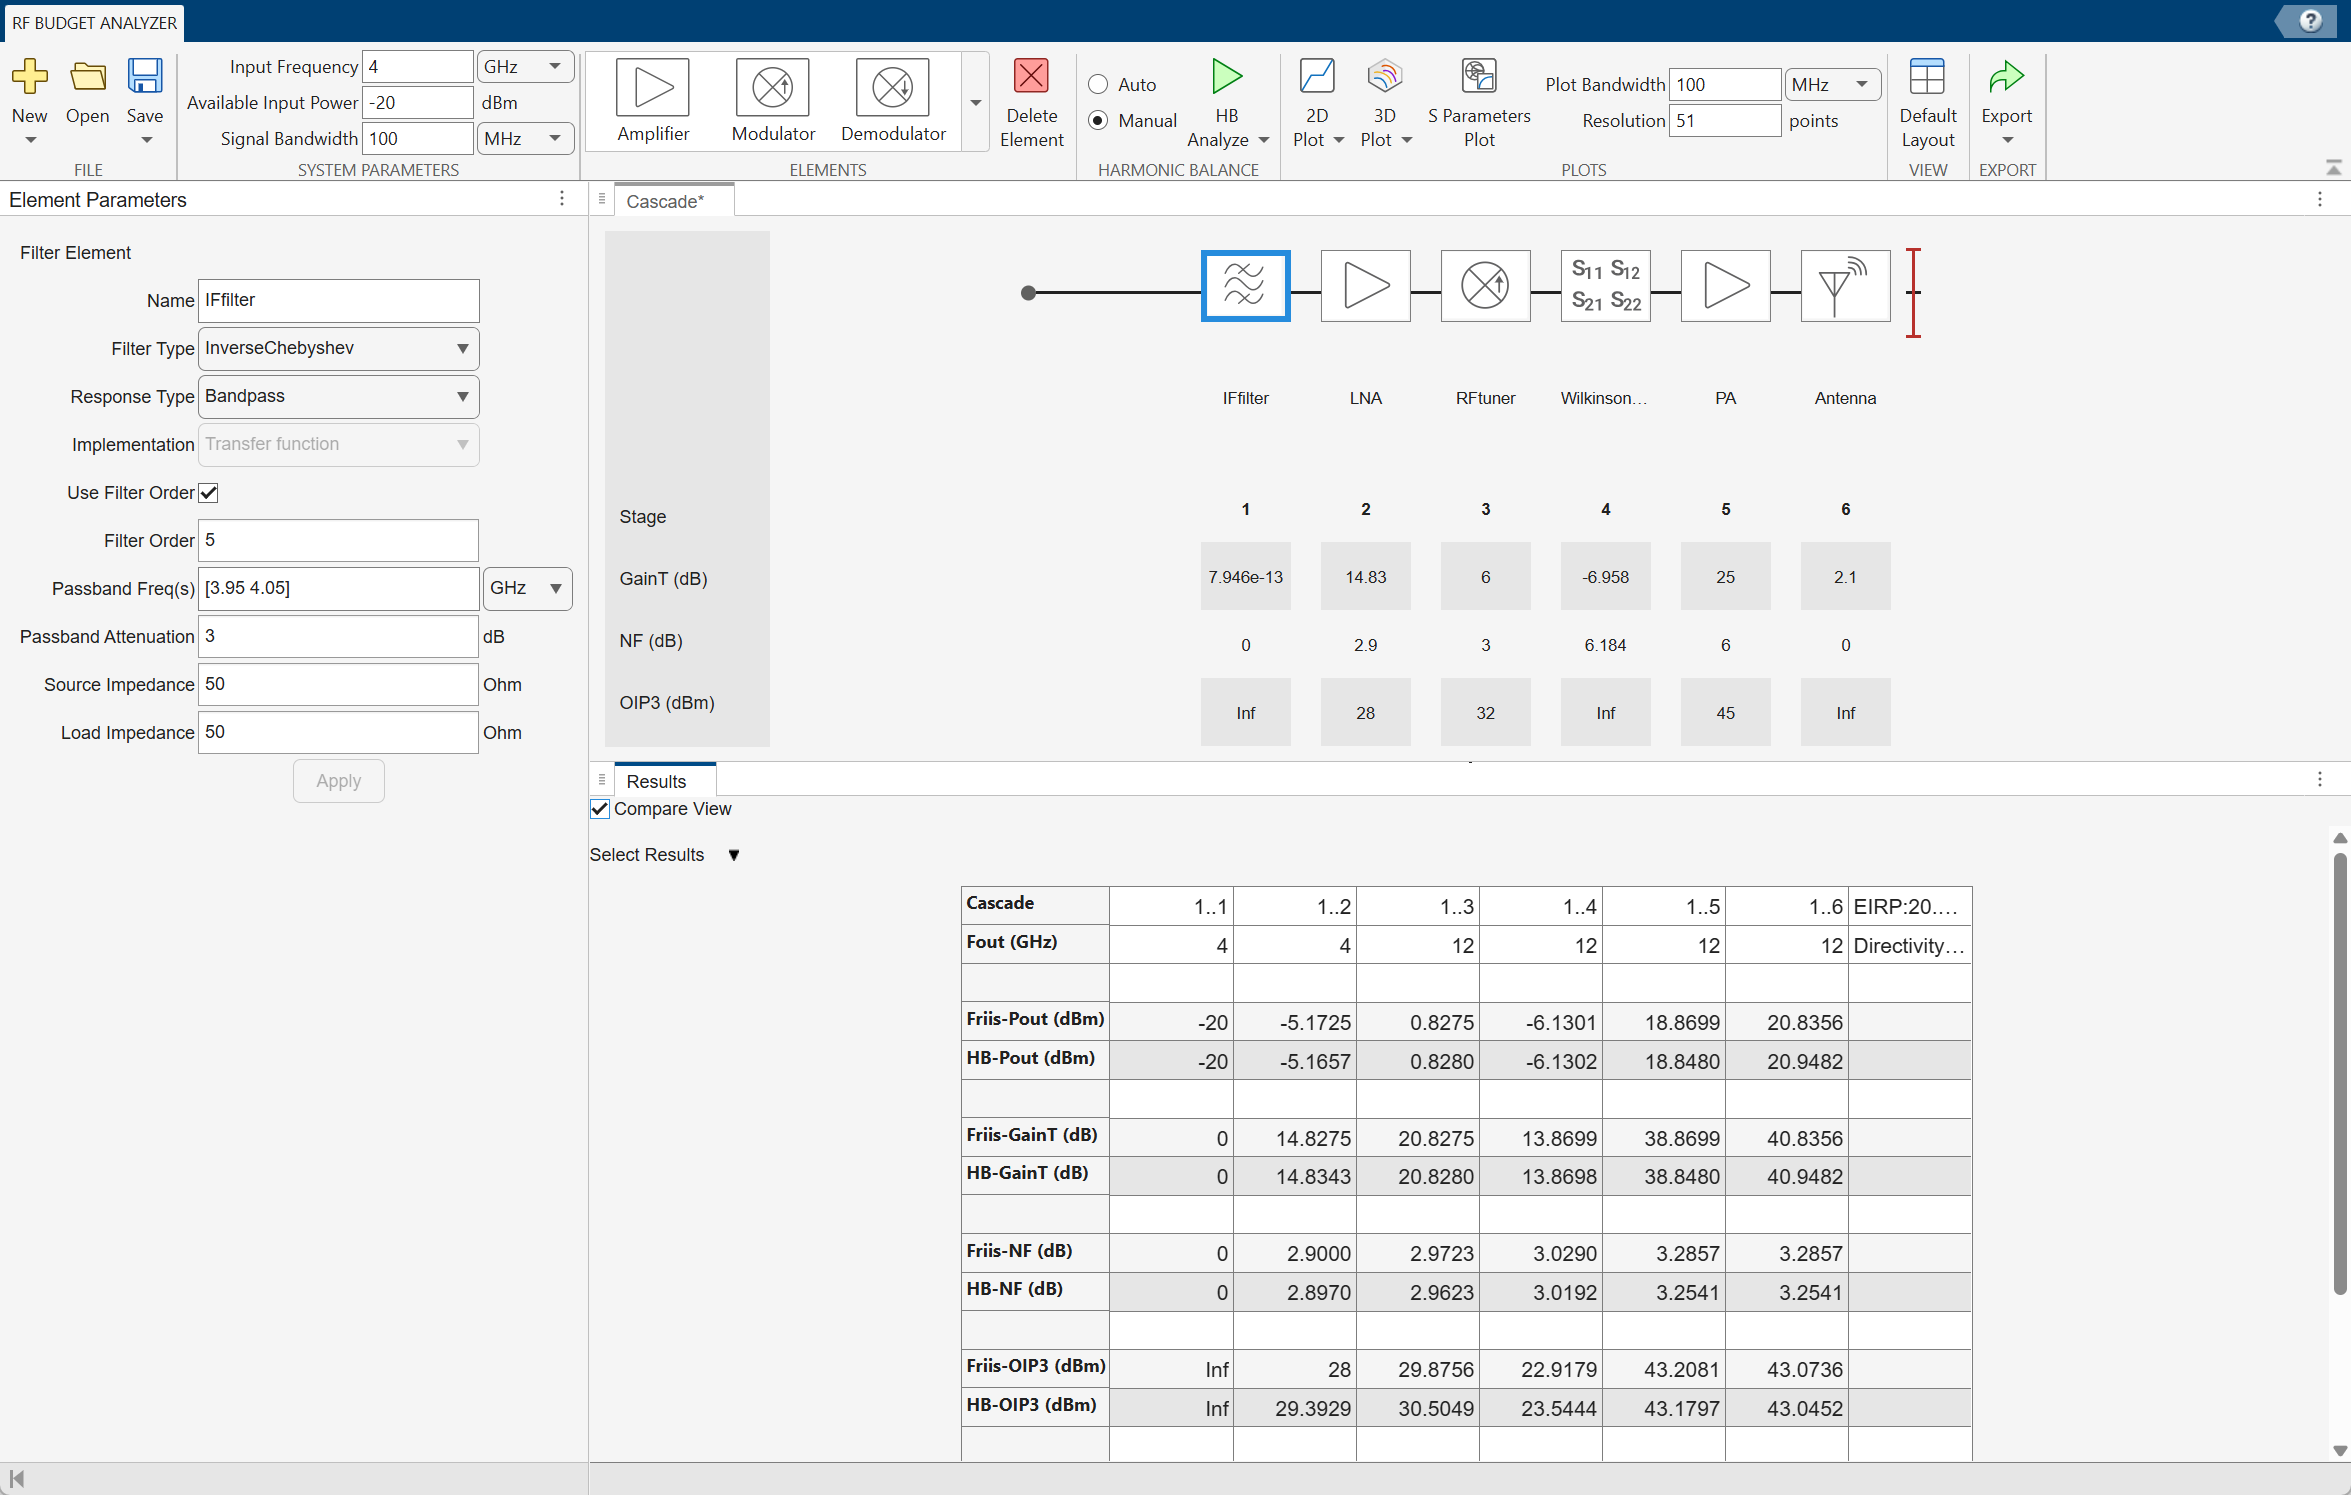

## Baseline - Compute expected max EIRP for the TX (4 elements)

First we analyze what is the predicted array output (N elements) power and gain **at the PA output port** (index 5), excluding antenna directivity. 

We estimate the antenna array gain, and coherently add the power.

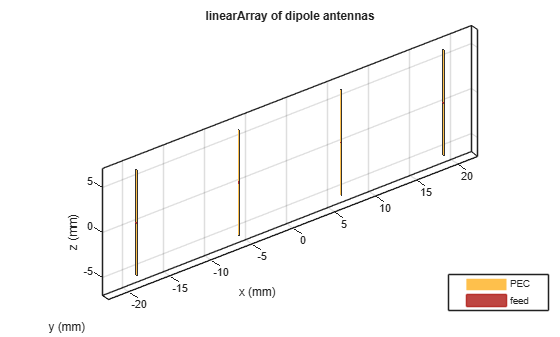

PA_idx = 5;
G2PAout = b.TransducerGain(PA_idx);
PAout = b.OutputPower(PA_idx);

antennaArray  = design(linearArray(Element=rfAntenna), fRF, rfAntenna);
antennaArray.NumElements = N;
figure; show(antennaArray)

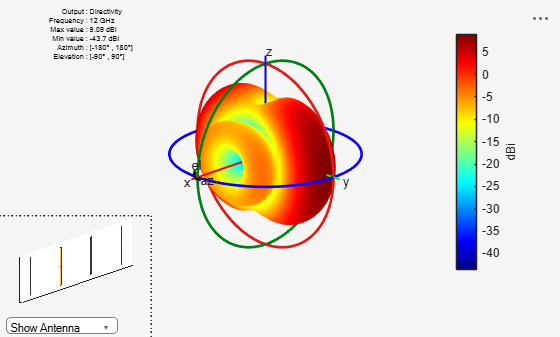

figure; pattern(antennaArray, fRF);

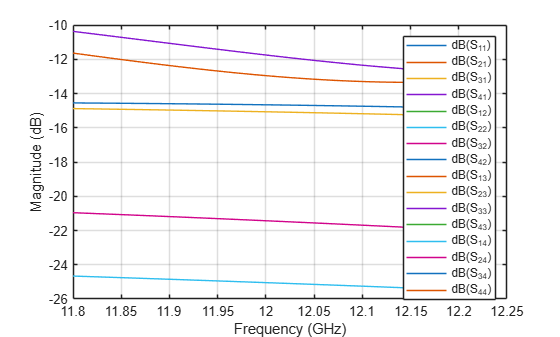

arrayDirectivity = peakRadiation(antennaArray, fRF);
arraySparam = sparameters(antennaArray, [-2*BW, 2*BW]+fRF, ...
    'SweepOption', 'interp');
figure; rfplot(arraySparam);

maxEIRP = PAout+arrayDirectivity+10*log10(N);
disp(['Pin = ' num2str(Pin) 'dBm']);

Pin = -20dBm


disp(['Expected PA Pout (budget) = ' num2str(PAout), 'dBm'])

Expected PA Pout (budget) = 18.8699dBm


disp(['Expected TX EIRP = ' num2str(maxEIRP), 'dBm'])

Expected TX EIRP = 33.9847dBm


## Signal Analysis - 5G 100MHz test waveform

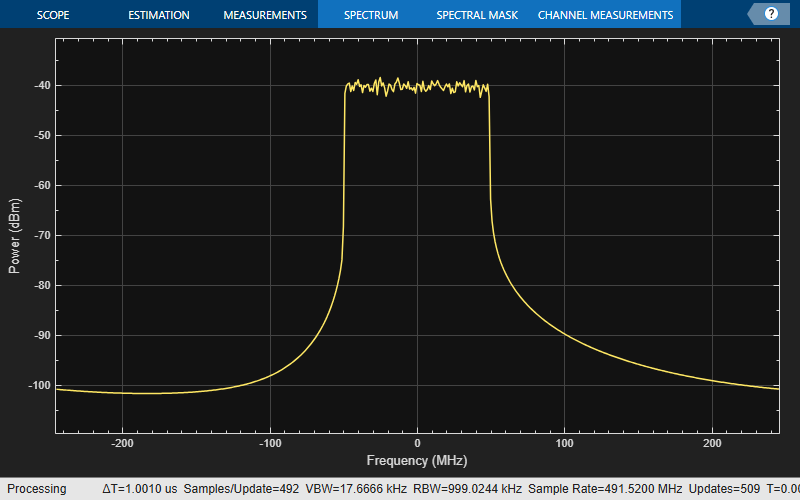

rc = "NR-FR1-TM3.1"; % Reference channel
bw = "100MHz"; % Channel bandwidth
scs = "30kHz"; % Subcarrier spacing
dm = "FDD"; % Duplexing mode

Tstep = 1/491.52e6;
Tstop = 0.51e-3;

tmwavegen = hNRReferenceWaveformGenerator(rc,bw,scs,dm);
tmwavegen = makeConfigWritable(tmwavegen);
tmwavegen.Config.SampleRate = 1/Tstep;
tmwavegen.Config.NumSubframes = 1;
[inWaveform,tmwaveinfo,resourcesinfo] = generateWaveform(tmwavegen,...
    tmwavegen.Config.NumSubframes);
inWaveform = inWaveform(1:round(Tstop/Tstep));

% Spectrum of 5G signal  
SpectAnalyzer = spectrumAnalyzer;
SpectAnalyzer.SampleRate = 1/Tstep;
SpectAnalyzer.ReferenceLoad = 1;
SpectAnalyzer.RBWSource= "Property";
SpectAnalyzer.RBW = 1e6;
SpectAnalyzer(inWaveform);

PowMet = powermeter("ReferenceLoad",1,"Measurement","All",...
    "WindowLength",length(inWaveform));
[AvgPow, ~,~] = PowMet(inWaveform);
inWaveform = inWaveform.*10^(-AvgPow(end)/20); %scale to 0dBm
release(PowMet);
[~,~,PAPRIn] = PowMet(inWaveform);
disp(['Input signal PAPR = ' num2str(PAPRIn(end)), 'dBm']);

Input signal PAPR = 10.3845dBm


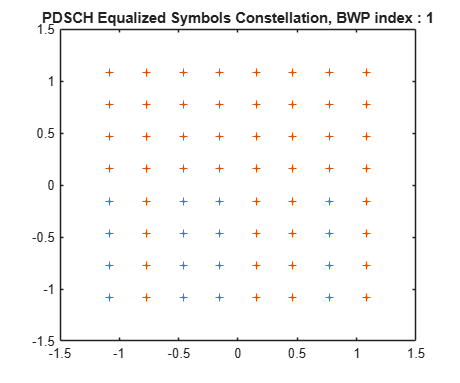

% EVM Measurement
cfg = struct();
cfg.Evm3GPP = false;
cfg.TargetRNTIs = [];
cfg.PlotEVM = true;
cfg.DisplayEVM = false;
cfg.Label = tmwavegen.ConfiguredModel{1};
cfg.UseWholeGrid = true;
cfg.PdcchEnable = false;
% Compute and display EVM measurements
[evmInfo,eqSym,refSym] = hNRDownlinkEVM(...
    tmwavegen.Config,inWaveform,cfg);

disp(['EVM RMS reference input waveform = ' num2str(evmInfo.PDSCH.OverallEVM.RMS*100) '%']);

EVM RMS reference input waveform = 2.5897e-14%


## Baseline EIRP and EVM - Run Simulation (Pin = -20dBm, dipole array)

load('modelTX.mat');
open_system(RF_TX);
Pin = -20; %dBm (already set)
clear outWaveform;
wvName =wvFileName(Pin, rfAntenna, N);
if loadOutWaveforms
    load(wvName);
else
    outWaveform = RF_TX(inWaveform);
    save(wvName,'outWaveform');
end

## Spectral measurement, power, and EVM

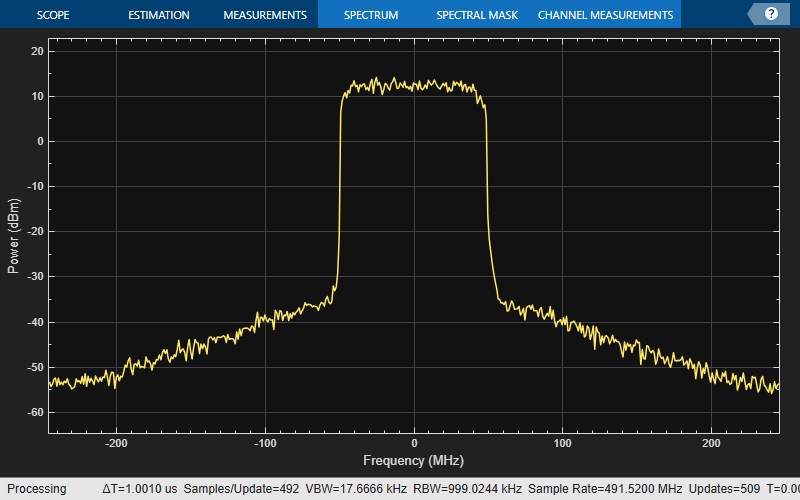

release(SpectAnalyzer);
SpectAnalyzer(outWaveform);

release(PowMet);
[AvgPowOut,~,PAPROut] = PowMet(outWaveform);
disp(['Measured TX EIRP = ' num2str(AvgPowOut(end)), 'dBm']);

Measured TX EIRP = 32.9759dBm


disp(['Output signal PAPR = ' num2str(PAPROut(end)), 'dBm']);

Output signal PAPR = 9.9858dBm


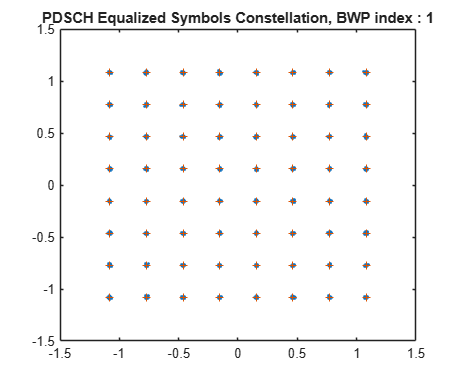

[evmInfo,~,~] = hNRDownlinkEVM(...
    tmwavegen.Config,outWaveform,cfg);

disp(['EVM RMS (at Pin=-20dBm) = ' num2str(evmInfo.PDSCH.OverallEVM.RMS*100) '%']);

EVM RMS (at Pin=-20dBm) = 0.5402%


Simulation shows excellent EVM (0.5%), and high linearity (ACPR~-50dBc). The EIRP matches the expected analytical results, but needs to be improved.